Question: 1.a)

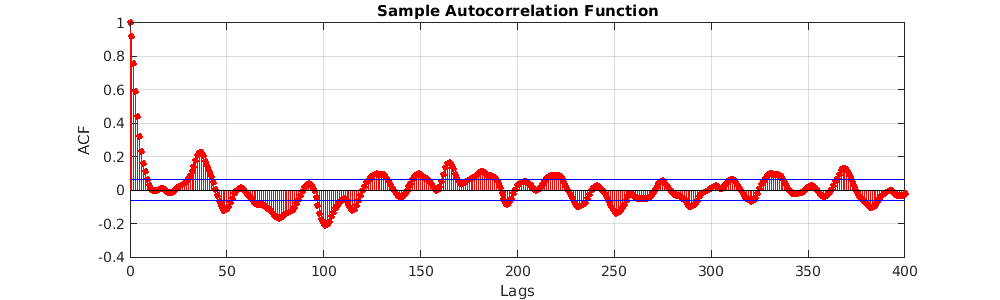

load("a4_timeseries.mat");
figure('Position', [10 10 1000 300])

autocorr(vk,'NumLags',400);
xlabel("Lags");
ylabel("ACF");

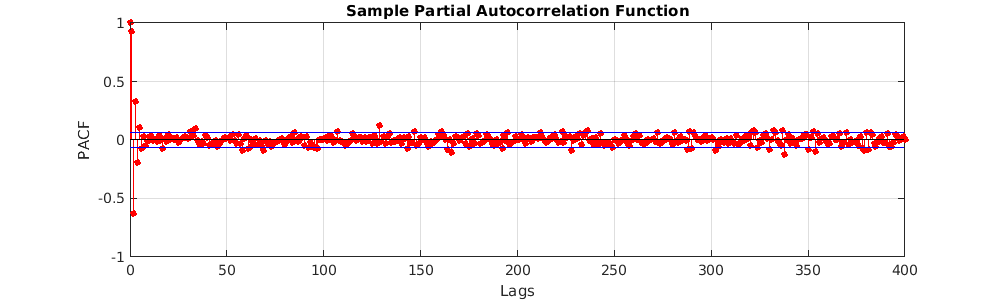

parcorr(vk,'NumLags',400);
xlabel("Lags");
ylabel("PACF");

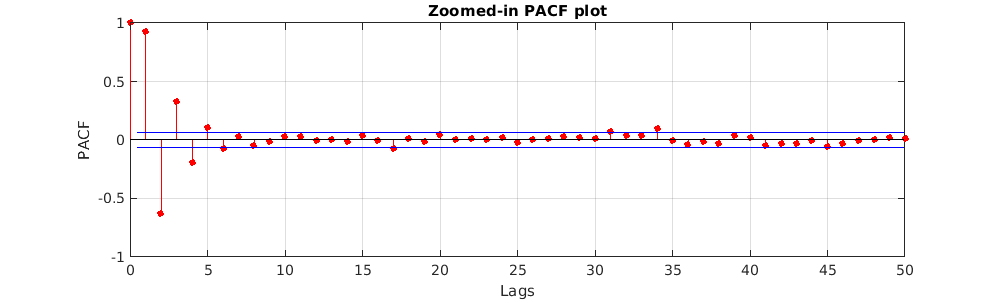

parcorr(vk,'NumLags',50);
xlabel("Lags");
ylabel("PACF");
title("Zoomed-in PACF plot")

Question: 1.b)

ar_model = ar(vk,5);
present(ar_model)

                                                                                                                                                  
ar_model =                                                                                                                                        
Discrete-time AR model: A(z)y(t) = e(t)                                                                                                           
  A(z) = 1 - 1.796 (+/- 0.03149) z^-1 + 1.405 (+/- 0.0639) z^-2 - 0.797 (+/- 0.07362) z^-3 + 0.3823 (+/- 0.06387) z^-4 - 0.1085 (+/- 0.03154) z^-5
                                                                                                                                                  
Sample time: 1 seconds                                                                                                                            
                                                                                                                      

Question: 3.b)

syms w;
gamma = (1/(2*pi)) * (1.68/ (2.5625 - 3.24 *cos(w/2)+ 0.7*cos(w))) * exp(1i*w*l);
acvf_int = int(gamma, w, -pi, pi);

k = zeros(1,15);
acvf = zeros(1,15);
for i = 0 : 15
    k(i+1) = i;
    acvf(i+1) = double(subs(acvf_int,l,i));
end

stem(k,acvf);

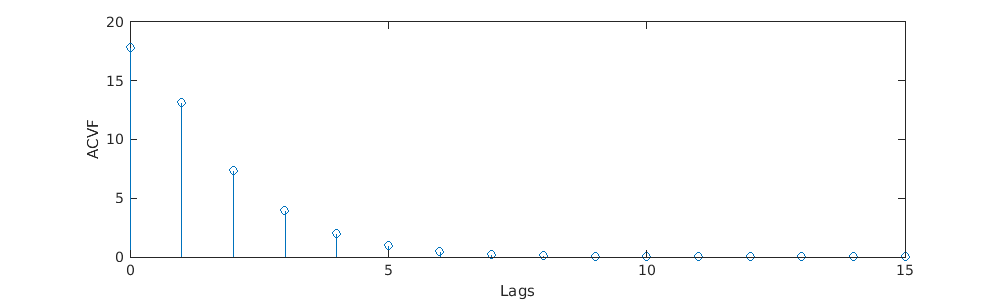

ylabel('ACVF')
xlabel('Lags');

syms theta
eqn = (3*3^0.5)*(1-cos(theta)) + 5*sin(theta) == 1;
double(solve(eqn,theta))

ans =    0.1836 - 0.0000i
  -1.7159 + 0.0000i
